# Estructuras de repetición: bucles

Los bucles (loops) se usan cuando necesita repetir un conjunto de instrucciones muchas veces. MATLAB soporta dos tipos diferentes de bucles: el bucle `for` y el bucle `while`.

La diferencia entre un bucle `for` y un bucle `while` es esta: bucle `for` cuando se conoce cuántas veces se quiere repetir el bucle, caso contrario se utiliza el bucle `while`.

Sin embargo, se pueden componer programas MATLAB que eviten los bucles, ya sea mediante el comando `find` o mediante la vectorización del código. (En la vectorización se opera sobre vectores enteros a la vez, en lugar de un elemento a la vez.) (Este tema se tratara en breve.) Es buena idea evitar los bucles siempre que sea posible, porque los programas resultantes corren más rápido y con frecuencia requieren menos pasos de programación.

## Bucles `for`

Este bucle es el más simple y ya se mencionó que se lo utiliza cuando se conoce el número de veces que se quiere repetir una instrucción, o varias.

Su sintaxis es como sigue:

Para explicarlo utilicemos un ejemplo: calcular la suma de los números enteros del 1 al que el usuario ingrese.

Pseudocódigo:

- Inicio.

- Solicitar el límite superior de la suma al usuario.

- Iniciar una variable donde se acumule la suma de los números.

- Determinar la suma de los números.

- Mostrar por pantalla el resultado.

- Fin.

Diagrama de flujo:

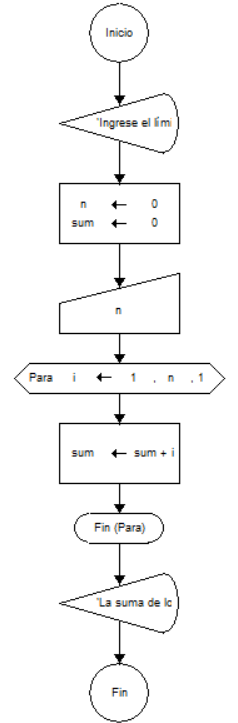

**Nota:** Aunque ya se lo ha mencionado repetidas veces, se recuerda que la nomenclatura de las figuras puede variar un poco según la fuente. En este caso se sigue utilizando el programa libre DFD para realizar los diagramas.

**Nota:** También cabe destacar que, aunque el diagrama no siga la secuencia estrictamente en el orden que está en el pseudocódigo (en este caso es por la naturaleza del programa libre DFD), la lógica sigue siendo la misma. Es decir, encontrar una solución al problema planteado. 

Código:

clear

n = input('Ingresar el límite superior de la suma: ');
sum = 0;

for i = 1:n
    sum = sum + i;
end

fprintf('La suma de los números enteros del 1 al %d es %d.',n,sum)

Hagamos un detalle minucioso de lo que está pasando dentro del bucle:

- Primero `i = 1` porque hemos indicado que el bucle va desde `1` hasta `n` con incremento de `1` (por defecto si no se especifica lo contrario).

- Entonces `sum = 0 + 1`. Por esta razón tuvimos que crear la variable `sum = 0`. O visto matemáticamente, la operación dentro del bucle es: $sum_{n+1} = sum_n + i$. Es decir, la suma siguiente será igual a la anterior más el índice. (Recuerda un poco a la sucesión de Fibonacci aunque esta depende sólo de un valor anterior, no de dos).

- Como la suma es la única instrucción, luego de hacerse con `i = 1` el bucle vuelve a iniciar con `i = 2`.

- Como ahora `i = 2` y `sum = 1`, tenemos que `sum = 1 + 2`. (Revisar lo explicado hace unos momentos si todavía no se entiende).

- Luego, como ya se hizo la suma y no hay más instrucciones, acaba la repetición con `i = 2` y cambia a `i = 3`.

- Como ahora `i = 3` y `sum = 1 + 2 = 3`, tenemos que `sum = 3 + 3`.

- Y así sigue hasta que `i = n` y se ejecute por última vez la instrucción, es decir, la suma.

Notemos algunos detalles del bucle:

- El índice (`i` en este caso) puede tomar cualquier nombre, aunque normalmente se le llame `i `(es un índice, no la unidad imaginaria). Recordar que este índice es el que tomará los valores del bucle (en este caso desde `1` hasta `n`).

- Para definir el número de veces que se repetirá el bucle basta con indicarle el inicio, el incremento y el final. (Recordar que si no se indica el incremento, por defecto MATLAB asume que es 1).

- La instrucción, o instrucciones, se ejecutarán tantas veces como se repita el bucle (en este caso `n` veces).

- El índice `i` vendría a ser una nueva variable que, al finalizar el bucle, tomará el valor de la última iteración (repetición). (Justamente porque es la última repetición). Sin embargo, casi nunca se trabaja con esta variable.

Un detalle que es importante resaltar es: la matriz de los valores que tomará el índice `i` puede ser cualquiera, no necesariamente tiene que tener alguna secuencia o ser unidimensional, aunque lo más común es trabajar con matrices unidimensionales (vectores).

Veamos lo siguiente:

clear

A = [
    1 8 4
    2 2 1
    2 6 9
    ];

for k = A
    a = 2*k
end

Analicemos el anterior código:

- Como el índice puede llamarse como se desee, en este caso se llamó `k`.

- Los valores para el índice, cuando se tiene una matriz bidimensional, es tomar cada vector columna y aplicar las instrucciones a este vector.

Sin embargo, como ya se mencionó repetidas veces, lo más usual es trabajar con vectores fila o columna para los valores que tomará el índice en lugar de trabajar con matrices bidimensionales.

### Aplicación: crear matrices

Una aplicación común es definir nuevas matrices:

clear

for i = 1:3
    D(i) = i^3;
end

disp(D)

Notemos que no hemos definido previamente ninguna matriz `D`, así que la estamos creando con este bucle.

#### Vectorización del código

La mayoría de los programas de cómputo no tienen la habilidad de MATLAB para manipular matrices tan fácilmente; por tanto, se apoyan en bucles similares al de crear matries para definir arreglos.

Comparemos esto:

Vector elevado al cubo mediante el ciclo `for`.

clear

for k = 1:3
    D(k) = k^3;
end

disp(D)

Vector elevado al cubo mediante operaciones.

k = 1:3;
D = k.^3;

disp(D)

¿Cuál es el código más óptimo? Evidentemente es el segundo en donde no utilizamos ningún bucle, bastó una operación simple.

A este proceso, crear un nuevo vector a partir de otro de la manera más óptima y eficiente posible, se le llama *vectorización del código*.

**Nota:** Aunque el concepto no aplica sólo a crear vectores, también aplica a cualquier código en general que se genere y se pueda optimizar. Pero al tema que concierne este capítulo, podemos utilizar la primera definición.

### Aplicación: combinar con estructura `if`

Veamos el siguiente ejemplo: en base a las notas finales de un grupo de Mecánica Newtoniana, determinar cuántos se quedan a supletorio.

clear

grades = randi(10,1,40)
count = 0;

for k = 1:length(grades)
    if grades(k) < 7
        count = count + 1;
    end
end

fprintf(['Del grupo de Mecánica Newtoniana de %d estudiantes, se quedan a supletorio %d.\n' ...
    'Es decir, el %.1f %% del curso tendrá que rendir el examen final.'], ...
    length(grades),count,count*100/length(grades))

### Resumen del bucle `for`

- La primera línea en el bucle define el número de veces que se repetirán los bucles mediante un número índice.

- El índice de un bucle `for` debe ser una variable. (El índice es el número que cambia cada vez a lo largo del bucle.) Aunque `i` con frecuencia se usa como el símbolo para el índice, se puede emplear cualquier nombre de variable. Otro nombre común es `k`.

- Cualquiera de las técnicas aprendidas para definir una matriz se puede usar para definir la matriz índice. Un enfoque común es usar el operador dos puntos, es decir,

- Si la expresión es un vector fila, los elementos se usan uno a la vez una vez cada que se les pasa por el bucle.

- Si la expresión es una matriz (esta alternativa no es común), cada vez que pasa por el bucle el índice contendrá la siguiente columna en la matriz. ¡Esto significa que el índice será un vector columna!

- Una vez que completa el bucle `for`, el índice es el último valor utilizado.

- Con frecuencia se evitan los bucles for al vectorizar el código.

## Bucles `while`

Este bucle se lo utiliza cuando no se conoce el número de veces que se quiere repetir una instrucción, o varias.

Su sintaxis es como sigue:

En este caso, como no sabemos cuántas veces se tiene que repetir el bucle no trabajamos con índices si no con una comparación lógica, o comparaciones.

Una vez se satisfaga la comparación (sea `true`) el bucle se detiene.

Otro detalle importante es que casi cualquier código que requiera repetición de instrucciones se puede hacer tanto con este bucle `while` como con el `for`. 

Para verificar la anterior sentencia hagamos el mismo ejercicio del bucle `for` pero con un bucle `while`: calcular la suma de los números enteros del 1 al que el usuario ingrese.

clear

n = input('Ingresar el límite superior de la suma: ');
sum = 0;
i = 1;

while i <= n
    sum = sum + i;
    i = i + 1;
end

fprintf('La suma de los números enteros del 1 al %d es %d.',n,sum)

Claro que quizá se piense ¿para qué tanto lío con dos bucles si con ambos se hace lo mismo? Y a primera vista se puede tener razón, sin embargo, dependiendo de la situación un bucle es más útil que otro.

Seamos más estrictos en el ejemplo anterior: calcular la suma de los números enteros del 1 al que el usuario ingrese siempre y cuando el número ingresado sea mayor o igual que 1. Si es menor solicitar otro número.

clear

n = input('Ingresar el límite superior de la suma: ');
sum = 0;

while n < 1
    n = input('El número debe ser mayor o igual que 1. Ingresar otro número: ')
end

for i = 1:n
    sum = sum + i;
end

fprintf('La suma de los números enteros del 1 al %d es %d.',n,sum)

Como podemos observar, del bucle while nunca se podrá salir a menos que se ingrese un número mayor o igual que 1. Así se garantiza que la suma que sigue sea válida.

Si se ha generado un bucle infinito bastará presionar **Ctrl + C** para interrumpir el bucle. En realidad esta combinación de teclas interrumpe la compilación, así que si se quiere interrumpir cualquier compilación también es posible usarla.

**Nota:** Pruebe a hacer un bucle infinito, es decir, un bucle `while` donde la condición nunca se satisfaga. Al hacer esto se entenderá por qué se debe tener cuidado con este bucle dado que se pueden generar este tipo de bucles infinitos sin querer.

### Aplicaciones

Como se ha mencionado, no hay casi nada que no se pueda con un bucle `while` que no se pueda hacer con un bucle `for`, o viceversa. Por ende, las aplicaciones vistas para el bucle `for` son las mismas para el bucle `while` con algunas ligeras diferencias. Bastará con analizar los dos ejemplos anteriores para notarlas.

## `Break` y `continue`

Los comandos `break` y `continue` permiten interrumpir el bucle o saltar a la siguiente iteración, respectivamente.

Veamos el siguiente ejemplo: determinar 10 veces el logaritmo natural de un número ingresado por teclado. Si el número mayor que 100, saltar ese cálculo. Pero si el número es menor que 1 interrumpir el bucle indicando error.

clear

for i = 1:10
    n = input('Ingresar un número: ');
    if n > 100
        disp('El número ingresado no es válido, sin embargo, puede ingresar otro.')
        continue
    elseif n < 1
        disp('Sólo se deben ingresar valores mayores o igual que 1.')
        disp('Fin del programa.')
        break
    end
    fprintf('El logaritmo natural de %.2f es %.2f.\n',n,log(n))
end

Como se puede observar en este ejemplo, si el número es mayor que 100 únicamente no toma en cuenta esa iteración y va a la siguiente. Sin embargo, si el número es menor que 1 ya no sigue iterando, es decir, interrumpe el bucle sin importar en qué iteración vaya.

No está demás decir que si el número es mayor o igual que 1 y menor o igual que 100 no entra al `if`. Únicamente devuelve el valor del logaritmo natural de ese número.

Si se repite el ejemplo anterior con el bucle `while`, únicamente habría que inicializar una variable que funcione de indicador para saber dónde termina el bucle.

**Nota:** *Inicializar* significa definir un valor de partida para una variable que cambiará más tarde.

## Cómo mejorar la eficiencia de los bucles

La recomendación es simple: no usar los bucles a menos que sea estrictamente necesario. Un código vectorizado es mil meces más eficiente que un código con bucles.

Para comparar el tiempo que tarda un código con bucles versus un código vectorizado se utilizará las funciones `tic` `toc`, que básicamente miden el tiempo transcurrido en que se realizan las instrucciones.

**Problema:** Sumar todos los elementos de una matriz `10000x100000`.

Código con bucles:

clear

A = randi(100,10000);
sum1 = 0;

tic
    for i = A
        for j = i'
            sum1 = sum1 + j;
        end
    end
toc

fprintf('La suma de los elementos de A es %d.',sum1)

Código vectorizado:

clear

A = randi(100,10000);

tic
    sum2 = sum(sum(A));
toc

fprintf('La suma de los elementos de A es %d.',sum2)

El tiempo transcurrido para la misma solución de un problema con código con bucles y código vectorizado es muy diferente: es más óptimo con código vectorizado.

Vale aclarar algunos puntos:

- El tiempo que se está midiendo es únicamente para las instrucciones que están entre las funciones `tic` `toc`.

- A su vez, para el tiempo medido se debe considerar que influyen los procesos en segundo plano de la PC, el rendimiento de esta, etc.

- El tiempo obtenido es para la PC del autor, sin embargo, este tiempo puede variar como ya se mencionó. Lo importante es comparar el tiempo que demora un código contra el otro.

- Claro que se puede pensar que son segundos o milésimas de segundo, que a breves rasgos parecería no ser mucho. Pero hay que considerar que esto fue para un sólo proceso y con una matriz medianamente grande. En general se suele trabajar con muchos procesos a la vez y con matrices todavía más grandes.

**Nota:** Para probar todavía más el tiempo entre un código y el otro se sugiere suprimir los punto y coma (`;`) de los procesos involucrados. El tiempo aumentará considerablemente y la diferencia será todavía más evidente. (Esta sugerencia es válida si se dispone de un ordenador medianamente potente).